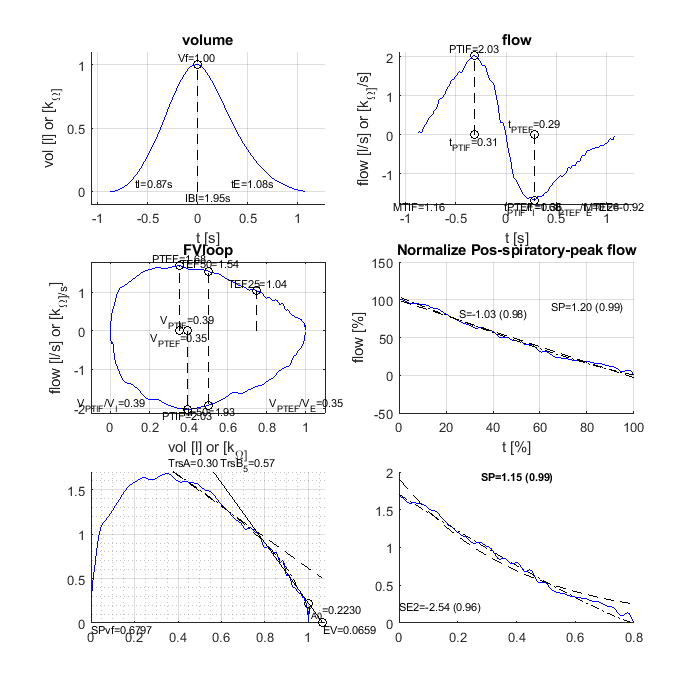

% This test file allows to test the 1 cycle linear parameters fuction in a respiratory cycle

addpath('respirationAnalysis\')

load('respiratory_cycle.mat')


fs = 256;%sampling frequency 

%integrate volume cycle from  flow
FMExpVolume = cumsum(FMExpFlow)/fs+1;
FMInspVolume = cumsum(FMInspFlow)/fs;


%chose the parameters to calculate
parNames = {'IBI','Vt','tI','tE'...
	,'PTIF','t_PTIF','MTIF','tPTIF_per_tI','V_PTIF','VPTIF_per_VI','TIF50'...
	,'PTEF','t_PTEF','MTEF','tPTEF_per_tE','V_PTEF','VPTEF_per_VE','TEF50','TEF25'...
	,'Sn','SEn','SP','SPn'...
	,'Trs','EV','SPvf','fA0'
	};



figure( 'Position', [0 0 700 700])

[ parValues , ~, parValues_conf ] = parameters1cycle( FMInspVolume, FMInspFlow, FMExpVolume, FMExpFlow, fs,'normalizeV','plot','parNames',parNames);



%parValues contain all the values oredered as parNames
%parValues_conf contain the confidence of fit, if parameters uses fitting 
array2table([parValues' parValues_conf'],'RowNames',parNames,'VariableNames',{'Values' 'confidenceFit'})

ans = 27×2 table
                     Values     confidenceFit
                    ________    _____________

    IBI               1.9531    1            
    Vt                     1    1            
    tI               0.87109    1            
    tE                 1.082    1            
    PTIF              2.0272    1            
    t_PTIF            0.3125    1            
    MTIF              1.1569    1            
    tPTIF_per_tI     0.35874    1            
    V_PTIF           0.39357    1            
    VPTIF_per_VI     0.39357    1            
    TIF50             1.9264    1            
    PTEF              1.6803    1            
    t_PTEF           0.28516    1            
   